# **Problema 4 - Primer parcial - Control**

## *Ortiz Hernandez Brayan*

## *Roque Guzman Ernesto*

### *5 7"*

4.- Con las funciones de las transformadas dadas, reducir y simular el esquema tal que obtenga el equivalente en lazo abierto. (4pts)

## Pasos preparatorios

clearvars
close all
clc

## Definiendo los bloques G

%Para G1 y G2
G1=30

G1 = 30

G2=2

G2 = 2

%Para G3
num3=1;
den3=[1 2 0];
G3=tf(num3,den3)

G3 =
 
      1
  ---------
  s^2 + 2 s
 
Continuous-time transfer function.
Model Properties


%Para G4
num4=2;
den4=[1 3];
G4=tf(num4,den4)

G4 =
 
    2
  -----
  s + 3
 
Continuous-time transfer function.
Model Properties


## Definiendo los bloques H

%Para H1
numH1=2;
denH1=[1 6];
H1=tf(numH1,denH1)

H1 =
 
    2
  -----
  s + 6
 
Continuous-time transfer function.
Model Properties


%Para H2
H2=0.1

H2 = 0.1000

%Para H3
numH3=[1 0];
denH3=[1 1];
H3=tf(numH3,denH3)

H3 =
 
    s
  -----
  s + 1
 
Continuous-time transfer function.
Model Properties


%Para H4
numH4=1;
denH4=[1 2];
H4=tf(numH4,denH4)

H4 =
 
    1
  -----
  s + 2
 
Continuous-time transfer function.
Model Properties


## Reduciendo


main=series(G4, 1/2);%bloque solo
main=minreal(main);
main=feedback(main, H3);

green=series(2, H4);
tempBlue=1/main;
blue=series(H2, tempBlue);

main=series(G3, main);
main=feedback(main, green);
main=series(G2, main);
main=feedback(main, blue);
main=series(G1, main);
main=feedback(main, H1)

main =
 
                  60 s^4 + 600 s^3 + 1740 s^2 + 1920 s + 720
  ---------------------------------------------------------------------------
  s^7 + 16 s^6 + 96.2 s^5 + 277.8 s^4 + 533.6 s^3 + 799.8 s^2 + 722 s + 259.2
 
Continuous-time transfer function.
Model Properties


## Graficando

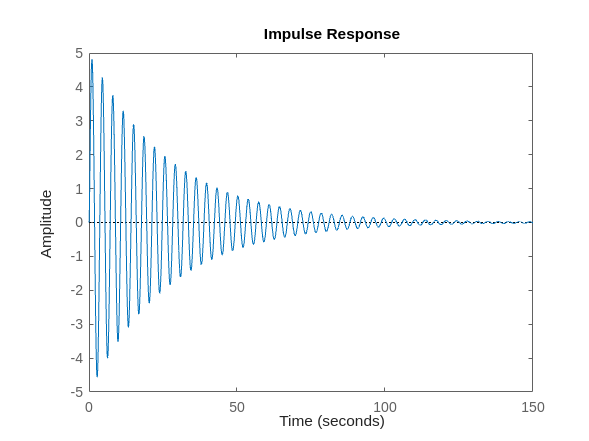

impulse(main)